**Projekt Bild**

**Karolina Utsi & Theo Wikström**

**Punkt 1 - Skapa spatiala bilder från 3D raw data (via iFFT).**

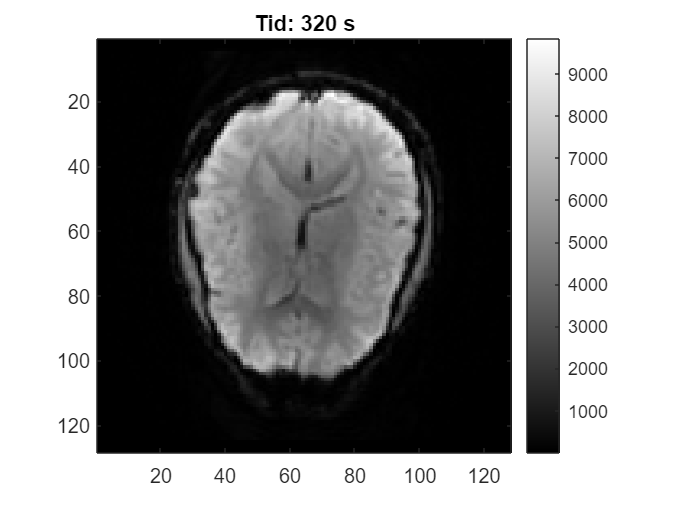

%% Load raw k-space data
load('Data/rawData.mat');  % justera sökvägen om det behövs

%% Skapa 3D-bilder via iFFT
% Antag att rawData heter 'kSpace' i filen och har dimensioner [X Y Z T]
% X, Y, Z = rumsliga dimensioner, T = antal tidssteg (160)

numTimepoints = size(kSpace,4);       % 160
img = zeros(size(kSpace));            % 4D-array för bilder (X x Y x Z x T)

for t = 1:numTimepoints
    k0 = kSpace(:,:,:,t);             % plocka ut k-space vid tid t
    img(:,:,:,t) = abs(fftshift(ifftn(ifftshift(k0))));  % iFFT och absolutvärde
end

%% Visa mittsnitt i z-led som animation
z_mid = round(size(img,3)/2);         % mitt i z-led

figure; 
for t = 1:numTimepoints
    imagesc(img(:,:,z_mid,t));
    colormap gray; 
    axis image; 
    colorbar;
    title(['Tid: ' num2str(t*2) ' s']);  % 2 s per bild
    pause(0.05);  % justera hastighet på animationen
end

**Punkt 2 - Bilderna kan innehålla små rörelseförändringar mellan mätpunkterna. Dessa kan korrigeras med ”motion correction”/”Image registration” i Matlab.**


%% Punkt 2: Motion correction / Image registration

% Använd första bilden som referens
refImg = img(:,:,:,1);
correctedImg = zeros(size(img));  % samma storlek som img

% Inställningar för registrering
[optimizer, metric] = imregconfig('monomodal');  % standardinställningar för monomodal MRI

for t = 1:numTimepoints
    moving = img(:,:,:,t);
    
    % Rigid registration: translation + rotation
    tform = imregtform(moving, refImg, 'rigid', optimizer, metric);
    
    % Applicera transformationen
    correctedImg(:,:,:,t) = imwarp(moving, tform, 'OutputView', imref3d(size(refImg)));
end

%% Visa mittsnitt efter motion correction
figure;
for t = 1:numTimepoints
    imagesc(correctedImg(:,:,z_mid,t));
    colormap gray; 
    axis image; 
    colorbar;
    title(['Tid (motion corrected): ' num2str(t*2) ' s']);  
    pause(0.05);
end


**Punkt 3 - Bilderna innehåller brus som behöver filtreras bort...**

**Punkt 4 - Skapa en tidsvektor som motsvarar hjärnans aktiveringsnivå. Utgå från aktiveringstider och HRF.**

**Punkt 5 - Hitta en korrelation mellan aktiveringssignal och voxlar (3D-pixlar).**

%...

**Punkt 6 - Rapportera funktionen av er metod...**